# ME441-001 Final Project

## Daniel Waggner + Corbin Strycker

Problem DFN:

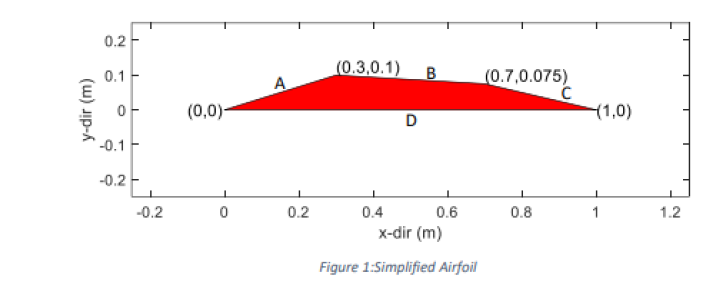

Initial CMDs

clear; 
clc;
close all;
format short;

Data

% Angle of Attack
alpha = 0; 
M1 = 3.0; 

Variable DFNs

% Flow Vector
flowVectorMag = 0.35;
flowVectorPosx = flowVectorMag * cosd(alpha);
flowVectorPosy = 1* flowVectorMag * sind(alpha); 

xvalstop = [flowVectorPosx, 0, 0.3, 0.7, 1.0];
yvalstop = [flowVectorPosy, 0, 0.1, 0.075, 0];

xvalsbottom = [flowVectorPosx, 0, 1.0];
yvalsbottom = [flowVectorPosy, 0, 0];

Assumptions:

    1. Acting Fluid is Air modeled as a callorically perfect gas

    2. Frictionless Flow (Inviscid)

gamma = 1.4;

Plotting Airfoil

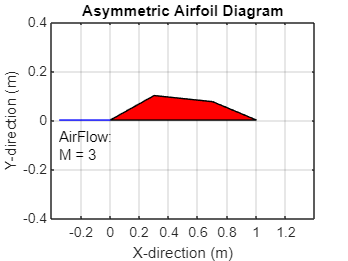

hold on;
fill(xvalstop, yvalstop, 'r');
xlim([-0.4 1.4]);
ylim([-0.4, 0.4]);
xticks(-0.2:0.2:1.2);

title("Asymmetric Airfoil Diagram");
xlabel("X-direction (m)");
ylabel("Y-direction (m)");
grid on; 
box on;

% Plotting Vector Line
plot([-1*flowVectorPosx, 0], [flowVectorPosy, 0], 'b');

% Velocity Labeling 
velStr1 = "AirFlow:";
velStr2 = append("M = ", num2str(round(M1,2)));
lableString = append(velStr1, velStr2);
text(-1*flowVectorPosx, flowVectorPosy-0.1, [velStr1, velStr2]);

Evaluating Flow Stuff

for i = 3:length(xvalstop)
    %DFN relative vectors
    x1 = xvalstop(i-2);
    x2 = xvalstop(i-1);
    x3 = xvalstop(i);

    y1 = yvalstop(i-2);
    y2 = yvalstop(i-1);
    y3 = yvalstop(i);

    if x2==0 && y2==0
        linfit = polyfit([x1, x2], [y1, y2], 1);
        x2 = 0.2;
        y2 = linfit(1)*x2 + linfit(2);
    end
    
    vec1coords = [x2, 2*x2; y2, 2*y2];
    vec2coords = [x2, x3; y2, y3];
    vec3coords = [2*x2, x3; 2*y2, y3]; 

    vec1length = sqrt((vec1coords(1,2) ...
        - vec1coords(1,1))^2 + (vec1coords(2,2) - ...
        vec1coords(2,1))^2);
    
    vec2length = sqrt((vec2coords(1,2) ...
        - vec2coords(1,1))^2 + (vec2coords(2,2) - ...
        vec2coords(2,1))^2);

    vec3length = sqrt((vec3coords(1,2) ...
        - vec3coords(1,1))^2 + (vec3coords(2,2) - ...
        vec3coords(2,1))^2);

    vec1 = [vec1coords(1,2) - vec1coords(1,1), ...
        vec1coords(2,2) - vec1coords(2,1)];

    vec2 = [vec2coords(1,2) - vec2coords(1,1), ...
        vec2coords(2,2) - vec2coords(2,1)];

    vec3 = [vec3coords(1,2) - vec3coords(1,1), ...
        vec3coords(2,2) - vec3coords(2,1)];
    
    %Compute Turning Angles via Vectors
    theta = acosd((vec1length^2 + vec2length^2 ...
        - vec3length^2) / (2 * vec1length ...
        * vec2length));     % degrees
    thetaDirection = AngleIn2D(vec1, vec2);
                            % radians
    
    %Evaluate Direction
    %   (-) Expansion Fans
    %   (+) Oblique Shocks

    if thetaDirection < 0 % expansion fan
        [M2, nu1, mu1] = flowprandtlmeyer(gamma, M1, 'mach');
        nu2 = nu1 - theta;
        [M1, nu2, mu2] = flowprandtlmeyer(gamma, nu2, 'nu');
        
        plot([x2, x2+3*cosd(nu1)],[y2, y2+3*sind(nu1)], 'r');
        plot([x2, x2+3*cosd(nu2)],[y2, y2+3*sind(nu2)], 'r');

    else % oblique shock
        beta = InvertTBM(theta, M1, gamma, 1);
        plot([x2, x2+3*cosd(beta)],...
            [y2, y2+3*cosd(beta)]);
    end
    
    
end

'fsolve' requires Optimization Toolbox.

Error in InvertTBM (line 19)
betaanswer = fsolve(@(beta)f(beta,theta,M), betaguess);